clear all; clc;

%
syms k integer;
n=3

n =      3


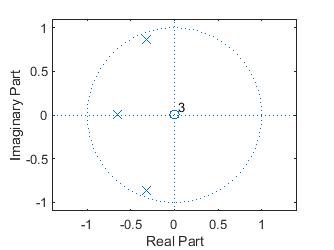

e=0.2;
theta(k)=(2*k-1) / (2*n) *pi;
beta(k)=asinh((1)^k/e)/(n);

sk(k)=tanh(beta(k)).*(-1).*sin(theta(k)) + j*cos(theta(k));


%syms s;
%H(s)=collect( prod( 1./(s-sk(1:n)) ))
%[num, den]= numden(1/H(0)*H(s));
%B=sym2poly(num);
%A=sym2poly(den);


A=poly( double(sk(1:n)) );
B=A(end)/A(1);

zplane( [B zeros(1, n- length(B)+1) ], [ A zeros(1, n- length(A)+1)] )

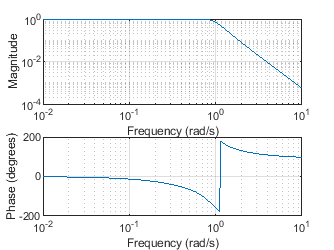



freqs(B,A);